**Name:** Shazzad Ahmed 

**ID:** 220021108

# **Assignment-7**

Exercise-1 test cases: Comma Check

q1=input('How many test cases : ');
for j=1:q1
    userInput=input('Enter string: ', 's')
    comma_check(userInput)
end

userInput = 'Logan ,you still have time.'

ans = 'Logan, you still have time.'

userInput = 'Evil is evil. Lesser ,greater ,middling – makes no difference.'

ans = 'Evil is evil. Lesser, greater, middling – makes no difference.'

userInput = 'He is the white wolf, the king in the North.'

ans = 'He is the white wolf, the king in the North.'

Exercise-2 test cases:Capital

q2=input('How many test cases : ');
for j=1:q2
    userInput1=input('Enter string: ', 's')
    capFirst(userInput1)
end

userInput1 = 'pandas'

ans = 'Pandas'

userInput1 = 'Cats and Dogs'

ans = 'Cats and dogs'

userInput1 = '763potus'

ans = '763Potus'

Input={'**GldosgGf', 'asbd', '$$$123', 'ASDR'}

Input = 1×4 cell array
    {'**GldosgGf'}    {'asbd'}    {'$$$123'}    {'ASDR'}


capFirst(Input)

ans = 1×4 cell array
    {'**Gldosggf'}    {'Asbd'}    {'$$$123'}    {'Asdr'}


Exercise-3 test cases:Iccanobif Sequence

icc(8)

ans = 39

icc(9)

ans = 124

icc(30)

ans = 94367798

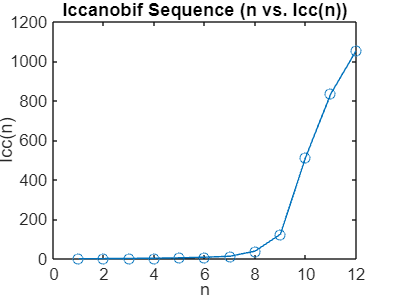

N=12;
y=zeros(1,N);
for k=1:N
    y(k)=icc(k);
end
plot(1:N,y,'o-')
xlabel('n')
ylabel('Icc(n)')
title('Iccanobif Sequence (n vs. Icc(n))')

Is vectorization possible?

Ans: Not easily because each term needs digit‑wise string ops (`num2str`→`fliplr`→`str2double`), it can’t fuse it into one matrix operation. The best I can do is preallocate my result (`a = zeros(1,N); a(1:2)=1;`) and then compute each term in a simple loop to avoid resizing overhead.

Exercise-4 test cases:

q3=input('How many test cases: ');
for j=1:q3
    mat=input('Enter matrix: ')
    a=input('Enter an integer: ')
    strr=input('Enter your string and press Enter: ', 's')
    disp(mat_out(mat, a, strr))
end

mat =    261   107   255   390     1    86   327   336   126   341   150   309   311     1   154   187
   207   302   320    79   114   208    76   149   358   224    89   306   201     2   279   200
   131   360   201    45   221   396    50   332    99   361    88   169   171    35   252   195
   265   292   261   119   349   196   329    71   125   168   209    23   245   105   181    92
    48   163   319   159    17   278   256    52   164   144   174   235   343    10   190    35
    60   376    94   169   362   165     7   352   284   196   297    70   269   170   380    27
     8   103   241   125    53    14   359    18    58   103    29   292   210   137    34   356
   386   214    45   278   334   118   207   275   349   372   339   214   120   217   112    94
   389   382   207    37   321   321   218   294    34   187   272   102   282   371   179   345
    50   108   336   161   368   139   243   175   185   102    55   367   153   120   236   285


a = 3

strr = 'mean'

  238.2222  171.1111  205.8889  226.3333  156.2222  194.0000
  208.6667  201.5556  182.2222  168.4444  210.3333   51.3333
  219.4444  177.8889  201.3333  212.2222  184.6667  265.0000
  220.6667  156.2222  234.4444  229.1111  234.7778  337.0000
  196.5556  167.8889  169.0000  166.6667  237.0000  202.3333
  152.6667  209.3333  162.3333  172.0000  338.3333  258.0000



mat =    400     2     3   397   396     6     7   393   392    10    11   389   388    14    15   385   384    18    19   381
    21   379   378    24    25   375   374    28    29   371   370    32    33   367   366    36    37   363   362    40
    41   359   358    44    45   355   354    48    49   351   350    52    53   347   346    56    57   343   342    60
   340    62    63   337   336    66    67   333   332    70    71   329   328    74    75   325   324    78    79   321
   320    82    83   317   316    86    87   313   312    90    91   309   308    94    95   305   304    98    99   301
   101   299   298   104   105   295   294   108   109   291   290   112   113   287   286   116   117   283   282   120
   121   279   278   124   125   275   274   128   129   271   270   132   133   267   266   136   137   263   262   140
   260   142   143   257   256   146   147   253   252   150   151   249   248   154   155   245   244   158   159   241
   240   162   163   237  

a = 5

strr = 'min'

     2     6    11    18
   101   108   112   116
   118   111   106   102
    16    12     8     1



mat =     92    99     1     8    15    67    74    51    58    40
    98    80     7    14    16    73    55    57    64    41
     4    81    88    20    22    54    56    63    70    47
    85    87    19    21     3    60    62    69    71    28
    86    93    25     2     9    61    68    75    52    34
    17    24    76    83    90    42    49    26    33    65
    23     5    82    89    91    48    30    32    39    66
    79     6    13    95    97    29    31    38    45    72
    10    12    94    96    78    35    37    44    46    53
    11    18   100    77    84    36    43    50    27    59


a = 5

strr = 'max'

    99    75
   100    72



mat =    359    15    97    20   360   233    78   273   371   356   343   184   374    28   280   196   298   350   393    21   381   229   141
   193   355   261   114   210   169   247   167   296    44   360   289   328   164   229   200   121    29   206   274   391   393   192
     6    99   343   262    49    37   108   153   227   176    88   136   284    50   252   375    36   396   398   244    13   340   235
   250     4    34   196    72    10   224    86   388   113    31   161   298   178   352   156   331   370   183    88   198   114    59
    93   326   389   390   283   197   378   154   330   395   190   211   360   360   265    47   156   226   171   163   346   273   363
   211    57    13   300   333   112   286    12   384   244   335   358    27   142   351    97   311   173    86   252    98   144   257
   290   352   335   228    14   136   272   189   259   102   188   312   135    49   188   274    72   136    78   223   334   395    66
   243    39   335   

a = 3

strr = 'max'

   359   360   371   360   374   396   398   393
   389   390   388   395   360   370   346   363
   352   383   391   312   351   389   334   395
   378   355   380   349   286   400   362   325
   384   344   397   350   297   400   273   321
   320   360   264   360   268   381    98   176



mat =     92    99     1     8    15    67    74    51    58    40
    98    80     7    14    16    73    55    57    64    41
     4    81    88    20    22    54    56    63    70    47
    85    87    19    21     3    60    62    69    71    28
    86    93    25     2     9    61    68    75    52    34
    17    24    76    83    90    42    49    26    33    65
    23     5    82    89    91    48    30    32    39    66
    79     6    13    95    97    29    31    38    45    72
    10    12    94    96    78    35    37    44    46    53
    11    18   100    77    84    36    43    50    27    59


a = 5

strr = 'mmm'

Error using Assignment_07>mat_out (line 73)
Unrecognized input arguments

Exercise-5 test cases:

names = {'Harry James Potter','Eddard Ned Stark','Charles Francis Xavier' };
[MID, FIRST, FL, APP] = processNames(names);
disp('I.   Middle names:');

I.   Middle names:


disp(MID);

    {'James'}    {'Ned'}    {'Francis'}



disp('II.  First names only:');

II.  First names only:


disp(FIRST);

    {'Harry'}    {'Eddard'}    {'Charles'}



disp('III. First + Last:');

III. First + Last:


disp(FL);

    {'Harry Potter'}    {'Eddard Stark'}    {'Charles Xavier'}



disp('IV.  Full + Abbrev:');

IV.  Full + Abbrev:


disp(APP);

    {'Harry James Potter,HJP'}    {'Eddard Ned Stark,ENS'}    {'Charles Francis Xavier,CFX'}



Exercise-6 test cases:

show3DResults()

i)   2nd column of layer 3:
    22     7     6     5    16    35

ii)  3rd row    of layer 1:
    31     9     2    22    27    20

iii) Layer 2 after zeroing diagonal:
     0    41    13    44    10    87
    48     0    11    73    84    13
    48     8     0    23    98    84
    29    44    65     0    71    71
    44    44    44     2     0    19
     3    35    35    32    79     0

iv)  18th element now (row 6, col 3, layer 1):
   NaN

v)   Size after appending layer:
     6     6     5



Exercise-7:

C=rand(500,500,500);
tic
slice1=zeros(1,size(C,3)); 
for k=1:size(C,3)
    slice1(k)=mean(C(:,:,k),'all');
end
slice1

slice1 =     0.5003    0.5004    0.5010    0.5002    0.5005    0.5000    0.5005    0.5000    0.4996    0.4993    0.5002    0.5002    0.4996    0.5002    0.5004    0.5003    0.5006    0.5000    0.5004    0.5002    0.5002    0.5008    0.5008    0.5007    0.5006    0.5004    0.5004    0.4997    0.5005    0.5001    0.4997    0.5002    0.5002    0.4999    0.5000    0.5003    0.5000    0.4994    0.5005    0.4999    0.5007    0.5003    0.4998    0.4991    0.5001    0.5004    0.4997    0.5001    0.5007    0.4998


t1=toc;
tic
slice2=squeeze(mean(mean(C,1),2))' 

slice2 =     0.5003    0.5004    0.5010    0.5002    0.5005    0.5000    0.5005    0.5000    0.4996    0.4993    0.5002    0.5002    0.4996    0.5002    0.5004    0.5003    0.5006    0.5000    0.5004    0.5002    0.5002    0.5008    0.5008    0.5007    0.5006    0.5004    0.5004    0.4997    0.5005    0.5001    0.4997    0.5002    0.5002    0.4999    0.5000    0.5003    0.5000    0.4994    0.5005    0.4999    0.5007    0.5003    0.4998    0.4991    0.5001    0.5004    0.4997    0.5001    0.5007    0.4998


t2=toc;
loop_time=t1

loop_time = 0.4945

vectorized_time=t2

vectorized_time = 0.0441

times=[t1, t2];
[fastT,idx]=min(times);
speedup=max(times)/fastT;
names={'loop','vectorized'};
fprintf('%s is faster by %.4fx (loop=%.4fs, vec=%.4fs)\n',names{idx},speedup,t1,t2);

vectorized is faster by 11.2069x (loop=0.4945s, vec=0.0441s)


Exercise-8 test cases:

q4=input('How many test cases : ');
for j=1:q4
    userInput4=input('Enter an Array: ');
    slice_3d(userInput4);
end

maxSum = 20

k_max = 2

slice =      5     5
     5     5


maxSum = 136

k_max =      2
     3


slice =      7     8     9    10
     6     1     2    11
     5     4     3    12
    16    15    14    13


Exercise-9:

txt = ['On June 28, 1914, a quiet summer day in Sarajevo, Gavrilo Princip made a choice that echoed through history. ' ...
  'By July 28, 1914, exactly 30 days later, Austria-Hungary officially declared war on Serbia, marking the beginning of World ' ...
  'War I. As autumn set in, soldiers counted the days: 100 days of brutal trench warfare by November 11, 1914. The first ' ...
  'winter dragged into December 25, 1914—a Christmas Day declared a temporary truce in pockets, where German and ' ...
  'British troops shared bread and songs for just one day. Throughout 1915, battles raged on for 365 days straight, leading into 1916’s infamous Somme offensive, which began on ' ...
  'July 1, 1916, and lasted 141 days, dragging into the chilling dawn of November 18, 1916. Then, on March 8, 1917, Russia ' ...
  'began its upheaval, just 50 days before the tsar abdicated on April 27, 1917. ' ...
  'World War I finally ended on November 11, 1918, exactly 1,572 days after the assassination in Sarajevo. Only 21 years ' ...
  'later, Europe plunged back into conflict. On September 1, 1939, Germany invaded Poland, igniting World War II—766 ' ...
  'days after the signing of the Munich Agreement in September 1938. By May 10, 1940, just 252 days later, Germany had ' ...
  'swept through the Low Countries. In 1941, on June 22, Operation Barbarossa was launched, beginning a brutal Eastern Front. The war in Europe raged for ' ...
  '1,594 days until May 8, 1945—Victory in Europe Day. Meanwhile, in the Pacific, WWII spanned 2,194 days from ' ...
  'December 7, 1941 (Pearl Harbor) until September 2, 1945, the official end on the USS Missouri. ' ...
  'Each day—365 days in 1942, 365 in 1943, another 366 in leap-year 1944, and the final 244 days of 1945—brought another ' ...
  'statistic, another record: battles lasted 78 days, sieges endured for 872 days, victory celebrations lasted for weeks, and ' ...
  'mourning for years. Through those 5,768 days from Sarajevo to Missouri, lives were measured in dates: July 14, 1916, April 12, 1945, ' ...
  'September 1, 1939, and beyond. Each calendar turned—365 days, 366, 365, and etc.—etched into history. And through ' ...
  'every year, every month counted in days, human resilience, hope, and loss were written in the language of dates.' ];
digs=regexp(txt,'\d','match');      
digs=str2double(digs);
nums=regexp(txt,'\d+','match');     
nums=str2double(nums);
fprintf('i. Individual digits: [%s]\n', num2str(digs))

i. Individual digits: [2  8  1  9  1  4  2  8  1  9  1  4  3  0  1  0  0  1  1  1  9  1  4  2  5  1  9  1  4  1  9  1  5  3  6  5  1  9  1  6  1  1  9  1  6  1  4  1  1  8  1  9  1  6  8  1  9  1  7  5  0  2  7  1  9  1  7  1  1  1  9  1  8  1  5  7  2  2  1  1  1  9  3  9  7  6  6  1  9  3  8  1  0  1  9  4  0  2  5  2  1  9  4  1  2  2  1  5  9  4  8  1  9  4  5  2  1  9  4  7  1  9  4  1  2  1  9  4  5  3  6  5  1  9  4  2  3  6  5  1  9  4  3  3  6  6  1  9  4  4  2  4  4  1  9  4  5  7  8  8  7  2  5  7  6  8  1  4  1  9  1  6  1  2  1  9  4  5  1  1  9  3  9  3  6  5  3  6  6  3  6  5]


fprintf('ii. Whole numbers: [%s]\n', num2str(nums))

ii. Whole numbers: [28  1914    28  1914    30   100    11  1914    25  1914  1915   365  1916     1  1916   141    18  1916     8  1917    50    27  1917    11  1918     1   572    21     1  1939   766  1938    10  1940   252  1941    22     1   594     8  1945     2   194     7  1941     2  1945   365  1942   365  1943   366  1944   244  1945    78   872     5   768    14  1916    12  1945     1  1939   365   366   365]


Exercise-10 test cases:

q5=input('How many test cases : ');
for j=1:q5
    userInput5=input('Enter a string: ', 's')
    removeSpaces(userInput5)
end

userInput5 = 'H e l l o W o r l d'

ans = 'HelloWorld'

userInput5 = 'Cats and Dogs'

ans = 'CatsandDogs'

userInput5 = 'what door?'

ans = 'whatdoor?'

userInput5 = 'Hodor'

ans = 'Hodor'

Exercise-11 test cases:

q6=input('How many test cases : ');
for j=1:q6
    userInput6=input('Enter a string: ', 's')
    keep_Alphabet(userInput6)
end

userInput6 = 'Abc123 def-456* *'

ans = 'Abcdef'

userInput6 = 'Cats and Dogs'

ans = 'CatsandDogs'

userInput6 = 'AI@2025: Transforming! The_Future...'

ans = 'AITransformingTheFuture'

userInput6 = 'Autobots! Roll out'

ans = 'AutobotsRollout'

Exercise-1 function:

function out=comma_check(str)
    out1=regexprep(str,'\s+,',',');
    out=regexprep(out1,',\s*',', ');
end

Exercise-2 function:

function out=capFirst(in)
    if isstring(in) || ischar(in)
        C=cellstr(in);
    elseif iscell(in)
        C=in;
    else
        error('Input must be char, string, or cell-array of chars.');
    end
    outC=cell(size(C));
    for k=1:numel(C)
        s=lower(C{k});
        idx=regexp(s,'[A-Za-z]','once');
        if ~isempty(idx)
            s(idx)=upper(s(idx));
        end
        outC{k}=s;
    end
    if ischar(in)
        out=outC{1};
    elseif isstring(in)
        out=string(outC);
    else
        out=outC;
    end
end

Exercise-3 function:

function y=icc(n)
    if ~isscalar(n)||n~=fix(n)||n<1
        error('Input must be an integer')
    end
    rev=@(x) str2double(fliplr(num2str(x)));
    a=[1,1];
    for k=3:n
        a(k)=rev(a(k-1))+rev(a(k-2));
    end
    y=a(n);
end

squares = arrayfun(@(x) x.^2, 1:10)

Exercise-4 function:

function out=mat_out(matrix, a1, string)
    if ~ismember(string, {'max','min','mean'})
        error('Unrecognized input arguments');
    end
    [m,n]=size(matrix);
    nbm=ceil(m/a1);
    nbn=ceil(n/a1);
    out=zeros(nbm, nbn);
    for bi=1:nbm
        rows=(bi-1)*a1+(1:a1);
        rows=rows(rows<=m);
        for bj=1:nbn
            cols=(bj-1)*a1+(1:a1);
            cols=cols(cols<=n);
            block=matrix(rows,cols);
            switch string
                case 'max'
                    out(bi,bj)=max(block(:));
                case 'min'
                    out(bi,bj)=min(block(:));
                case 'mean'
                    out(bi,bj)=mean(block(:));
            end
        end
    end
end

Exercise-5 function:

function [MIDDLE, FIRST, FIRSTLAST, APPENDED]=processNames(NAMES)
    NAMES=strtrim(NAMES);
    n=numel(NAMES);
    MIDDLE=cell(1,n);
    FIRST=cell(1,n);
    FIRSTLAST=cell(1,n);
    APPENDED=cell(1,n);
    for i=1:n
        parts=strsplit(NAMES{i});
        f=parts{1};
        m=parts{2};
        l=parts{end};
        FIRST{i}= f;
        MIDDLE{i}= m;
        FIRSTLAST{i}=[f ' ' l];
        ABB=upper([f(1) m(1) l(1)]);
        APPENDED{i}=sprintf('%s,%s',NAMES{i},ABB);
    end
end

Exercise-6 function:

function show3DResults()
    a(:,:,1)=magic(6);
    a(:,:,2)=randi(100,6);
    a(:,:,3)=spiral(6);
    a(:,:,4)=eye(6);
    col2_l3=a(:,2,3);
    row3_l1=a(3,:,1);
    for d=1:6
        a(d,d,2)=0;
    end
    [i,j,k]=ind2sub(size(a), 18);
    a(i,j,k)=NaN;
    a(:,:,end+1)=1000;
    fprintf('i)   2nd column of layer 3:\n');
    disp(col2_l3')
    fprintf('ii)  3rd row    of layer 1:\n');
    disp(row3_l1)
    fprintf('iii) Layer 2 after zeroing diagonal:\n');
    disp(a(:,:,2))
    fprintf('iv)  18th element now (row %d, col %d, layer %d):\n', i, j, k);
    disp(a(i,j,k))
    fprintf('v)   Size after appending layer:\n');
    disp(size(a))
end

Exercise-8 function:

function [maxSum,k_max,slice]=slice_3d(A)
    s=squeeze(sum(sum(A,1),2));
    maxSum=max(s)
    k_max=find(s==maxSum)
    slice=A(:,:,k_max(1))
end

Exercise-10 function:

function out=removeSpaces(s)
    out=regexprep(s,'\s+','');
end

Exercise-11 function:

function out=keep_Alphabet(s)
    out=regexprep(s,'[^A-Za-z]','');
end